# Versao 1

clear all;
frase = Chave(3,20) % Ponto 1

frase = 'SKiNaBWYbKeOr'

hash=string2hash(frase,10000) % Ponto 2

hash = 6800

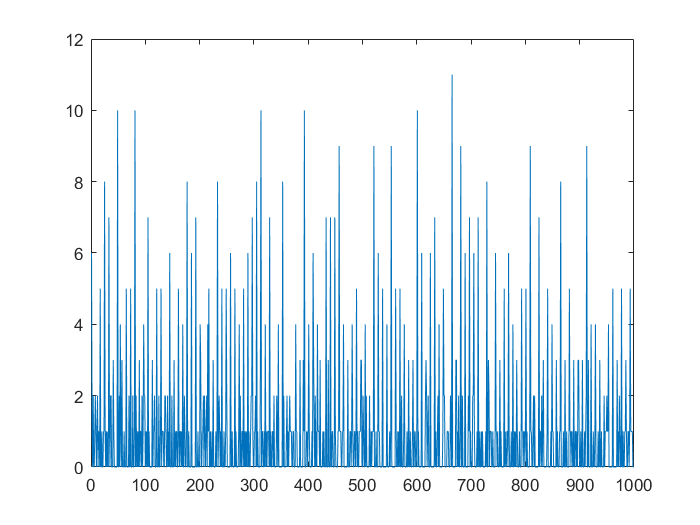

% Ponto 3
toHist = zeros(1,1000);
for i=1:1000
    frase1=Chave(3,20);
    hash1=string2hash(frase1,1000)+1;
    toHist(hash1)=toHist(hash1)+1;
end
plot(toHist) %numero de strings que foram mapeadas pela hash function para cada posicao

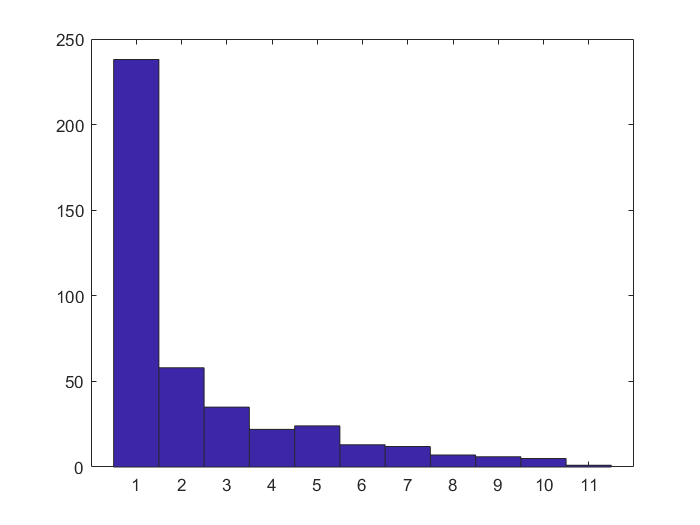

hist(toHist(toHist>0), 1:max(toHist)) %histograma desses numeros


%Ponto 4
n=zeros(1,1364);
for i=1:1000
    frase2=Chave(3,20);
    hash2=string2hash(frase2,1364)+1;
    n(hash2)=n(hash2)+1;
end
media=mean(n(n>0))

media = 1.7889

variancia=var(n(n>0))

variancia = 1.2457

function hash = string2hash(srt,N) %gerada no ponto 2
    res=0;
    for i=1:length(srt)
        res=srt(i)+res*37; %2^32-1 
    end
    hash=mod(res,N);
end
% gera um valor a partir da sequencia da srt

% gerada no ponto 1
function chave = Chave(lengthmin,lengthmax) 
    letras = ['a':'z','A':'Z']; %letras que podemos usar
    tamanho = randi([lengthmin lengthmax],1,1); %crias o valor aleatorio para o tamanho da string ...1,1 e uma matriz de 1 para 1 ou seja 1 valor
    %numel(letras) = numero de elementos do array letras
    indice = randi(numel(letras),[1 tamanho]); % seleciona as posicoes para colocar a string; da-nos uma matriz com os valores de 1 ate o valor
    chave = letras(indice); %como se percorre-se o sitio(de a(3) ate b(20)) onde esta a string num array
end